files = dir("load_disp_refine\*.csv");
files = files(1:end-1)

files = 10×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


max_disp = zeros(length(files),1);
for i=1:length(files)
    file = files(i,:);
    data = readmatrix(strcat(file.folder,"\", file.name));
    max_disp(i) = max(data(:,2));
end

Index in position 2 exceeds array bounds.

max_disp

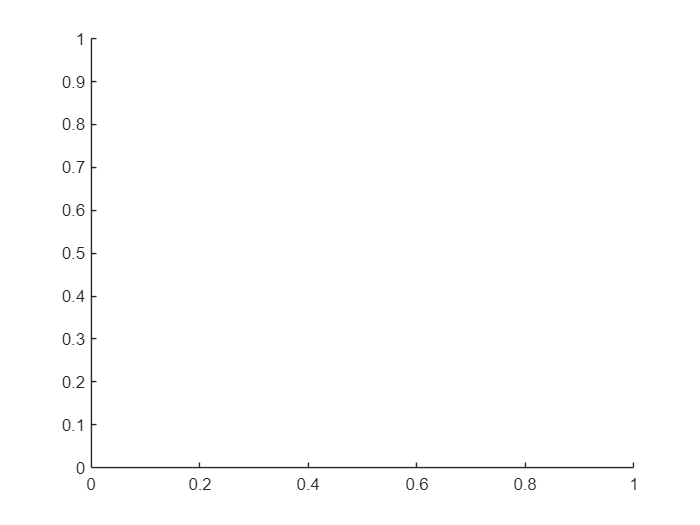

close all;
figure()
hold on;

for i = 1:length(files)
    file = files(i,:);
    data = readmatrix(strcat(file.folder,"\", file.name));
    plot(data(:,1),data(:,2),'DisplayName',file.name);
end

Index in position 2 exceeds array bounds.

legend()


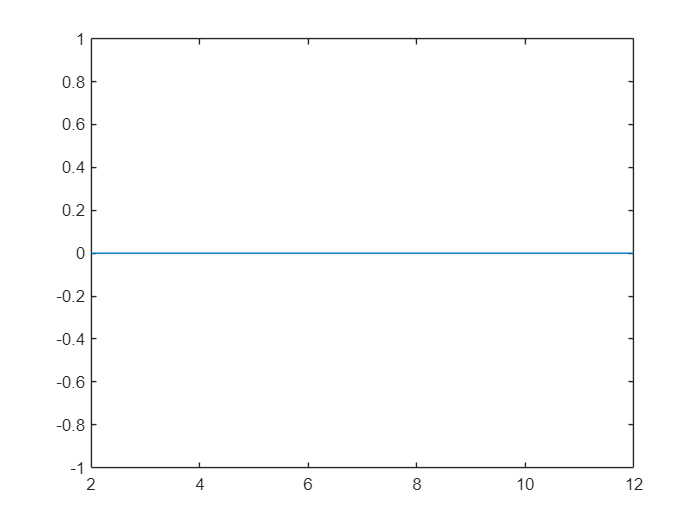

figure()
mps = (2:(length(files)+1));
plot(mps,max_disp)